# Pendulum exercise

Initialization part

clear all
close all
clc

% Initialize simulation variables
theta_setpoint = 1;  % [rad] set-point for the pendulum angular position
debug_mode = 0;      % debug mode flag (1=debug, 0=normal). If the debug mode is activated the controller plant becomes a pure double integrator
manual_control_flag = 1;    % flag to switch from manual to ADRC control (1=manual, 0=adrc)
u_manual = 0;   % [Nm] manual control action (motor torque), it is applied only if manual control is activated


% Desired closed-loop response characteristics
T_settle = 2;    %   [s] settling time
settling_perc = 5;     % desired percentage of the set-point for the settling time
xi = 1;     % desired closed-loop damping
omega_c = -log(0.01*settling_perc)/(T_settle*xi);   % [rad/s] desired closed-loop bandwidth

% Simulation settings
Tsim = 10;
rel_tol= 1e-6;

% Initialize pendulum variables
M = 0.5;    % [kg] mass of the pendulum tip
l = 0.3;    % [m] length of the pendulum rod
c = 0.1;    % viscous friction coefficient
g = 9.81;    % [m/s^2] acceleration due to gravity

% Sensor noise
pow = 0;
Ts = 1e-3;

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 


% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
omega_o = 40*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];
L = [ l1 ;
      l2 ;
      l3 ];

## Debug

First we perform a debug to be sure that we have implemented correctly the Extended state observer (ESO) and the state-feedback controller.

Thus, we enable the debug mode and the controlled plant becomes a pure double integrator. This means that the model implemented in the ESO perfectly matches the model of the plant. So, we are expecting that the closed-loop response perfectly matches the one we have imposed when designing the state-feedback controller.

To verify this we plot the set-point following closed-loop response and we compare it with the theoretical one that we have considered to tune the gains of the state-feedback controller.

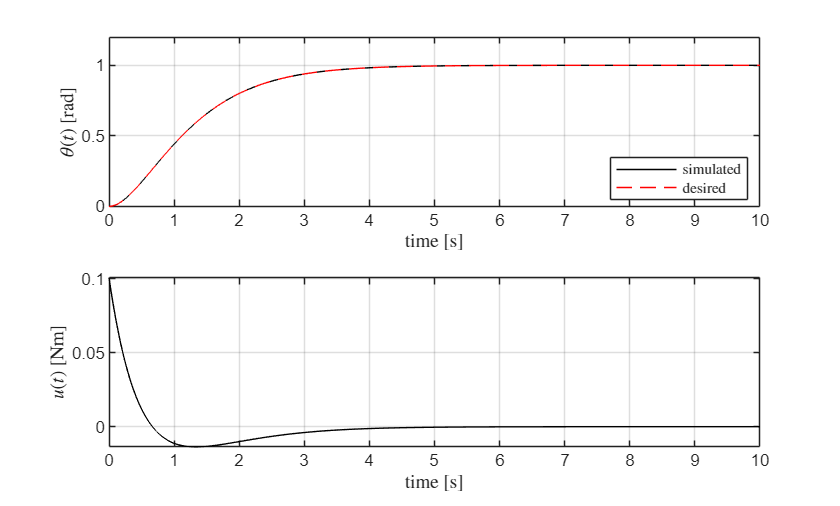

debug_mode = 1;      % debug mode flag (1=debug, 0=normal)

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

We notice that the simulated response perfectly matches the desired one. This means that we have implemented everything in the right way.

We check also the states reconstructed by the ESO and we compare them with the real one of the plant.

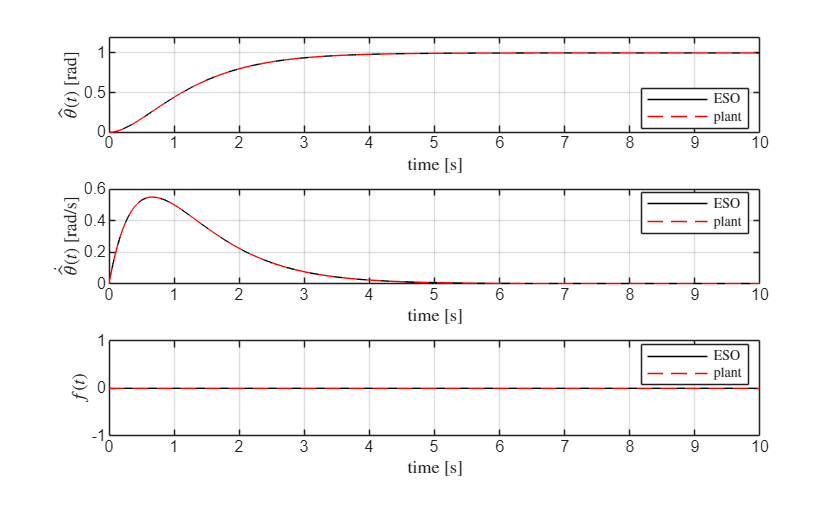

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

We see that the states estimated by the ESO perfectly match those of the double integrator plant.

Note that the total disturbance term is equal to zero, this is because the model implemented in the ESO (the enforced plant) perfectly matches the controlled plant.

However, this was only for debug purposes. So now we considered the true plant.

First, to check if we have implemented the pendulum model correctly we perform an open-loop simulation by letting start the pendulum from an initial angle different from zero and we plot the response.

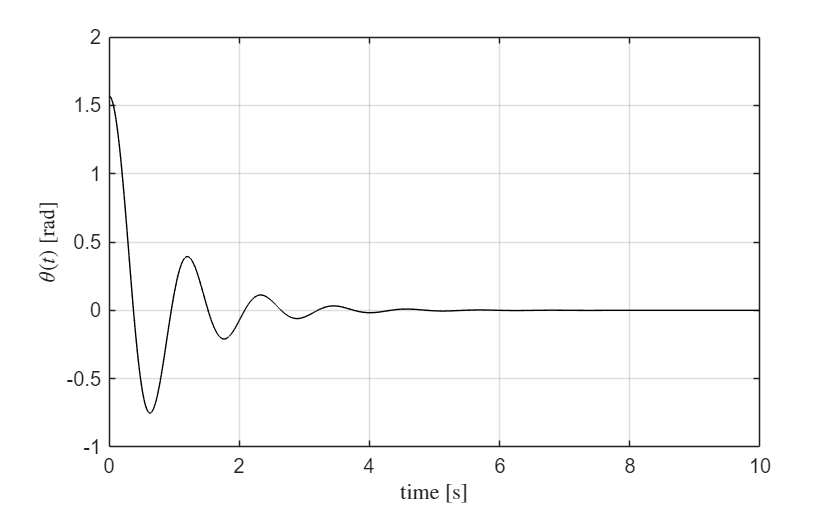

debug_mode = 0;      % debug mode flag (1=debug, 0=normal)
manual_control_flag = 1; % flag to switch from manual to adrc control (1=manual, 0=adrc)

theta_init = pi/2; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t_ol = simout.tout;
theta_ol = simout.yout{1}.Values.Data;

% Plot the results of the simulation
figure;
plot(t_ol, theta_ol, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;

The behavior of the model is sensible, if we let the pandulum fall freely in oscillates and then it settles in vertical position.

Then, to check that the input part of the pendulum model is correct we give as input the torque necessary to keep the pendulum steady in the initial conditions and we check the results.

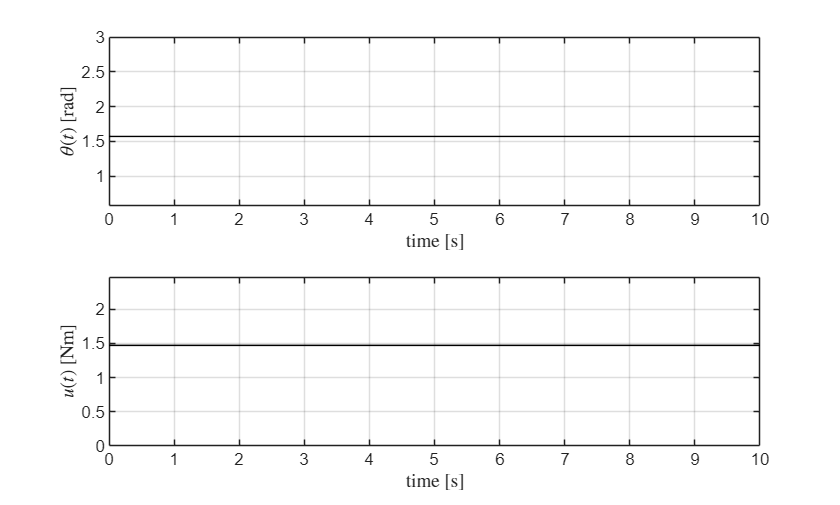

u_manual = M*g*l;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

The result matches the expectation.

To further verify the model, we initialize the pendulum to its stable vertical position end we check the effect of applying a motor torque.

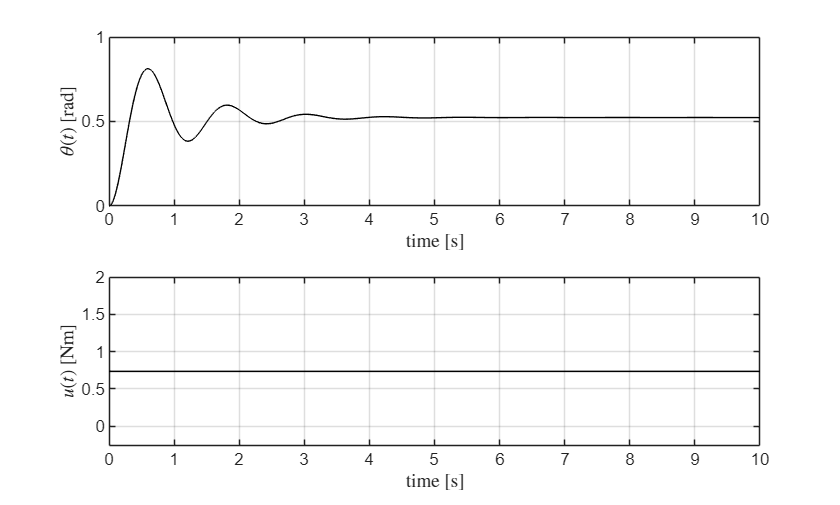

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

u_manual = (M*g*l)/2;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

As expected, by applying a motor torque the pendulum departs from its equilibrium position and settles to an angle different from zero.

We also check the states estimated by the ESO.

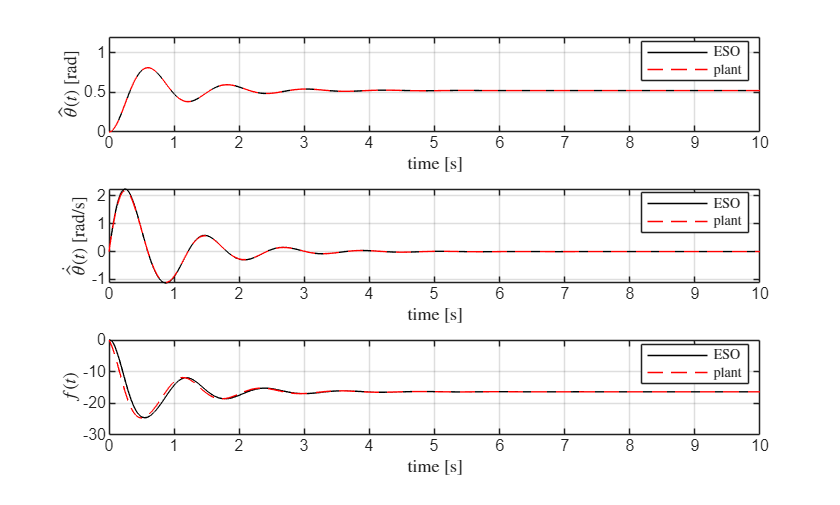

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

Note that now the total disturbance term is different from zero because the actual plant differes from the ideal double integrator plant.

However, the ESO is doing a good job in properly estimating the states of the actual plant.

## Closed-loop simulation

### Nominal case

Now we perform a closed-loop simulation by enabling the ADRC controller and we check if the control specifications are met.

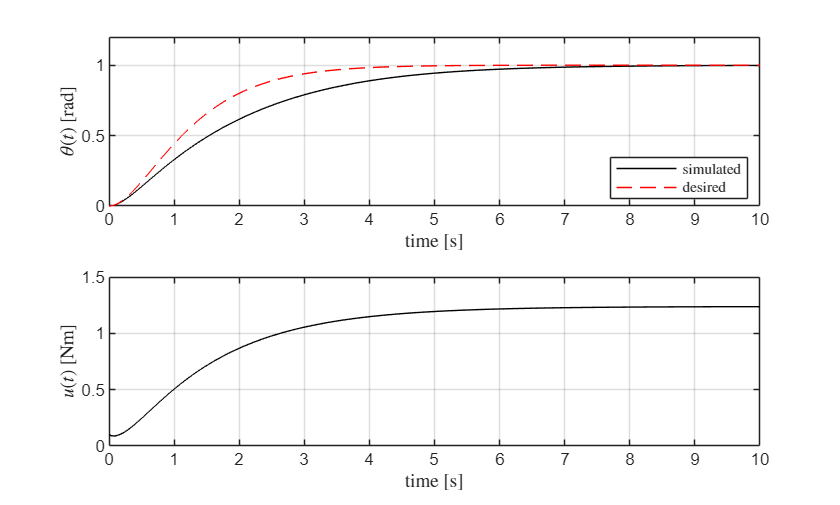

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

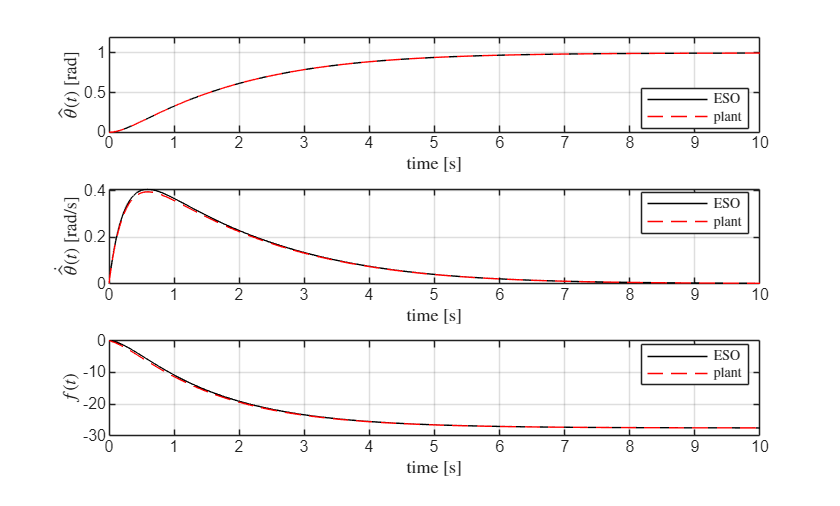

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

We see that the specification in the settling time is not satisfied, so we adjust the closed-loop bandwidth to meet the specification

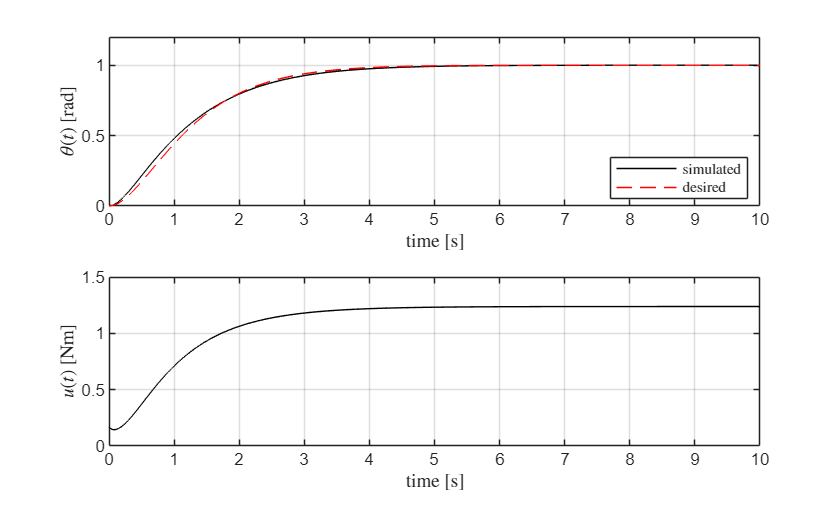

omega_c = omega_c*1.3;
k1 = omega_c^2;
k2 = 2*xi*omega_c;

omega_o = 40*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

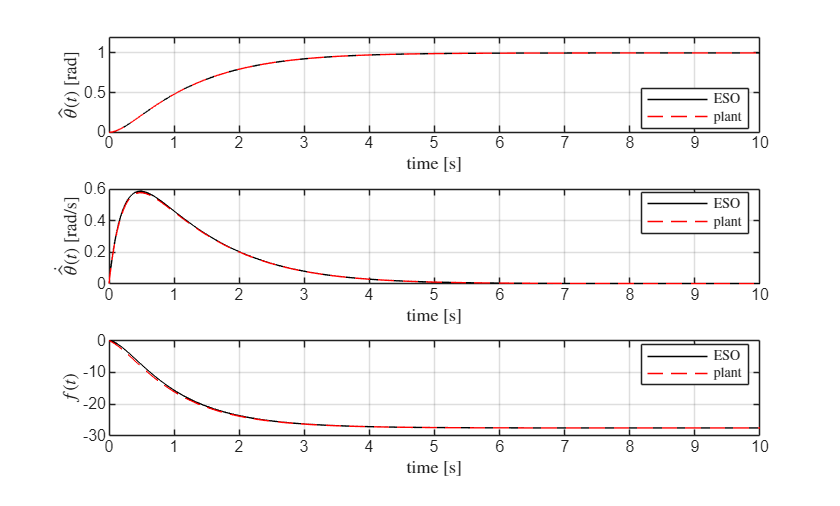

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

Now we consider measurement noise.

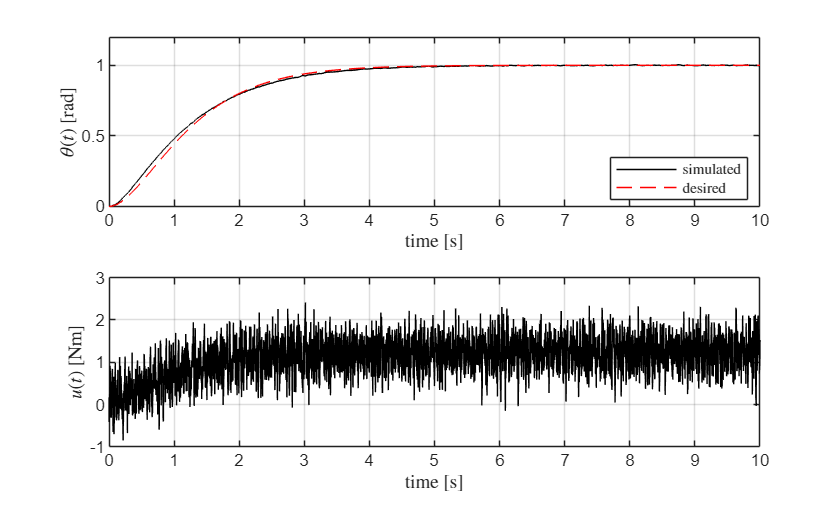

% Sensor noise
pow = 1e-7;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

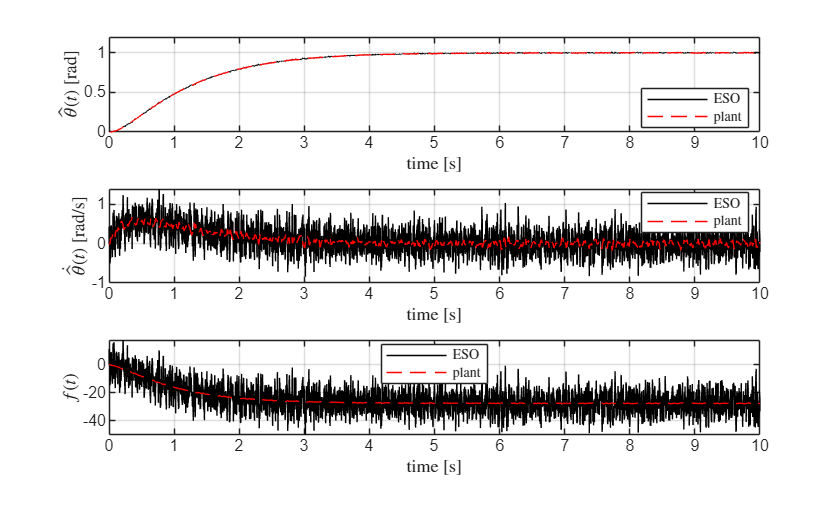

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

Adjust the observer bandwidth to cope with noise

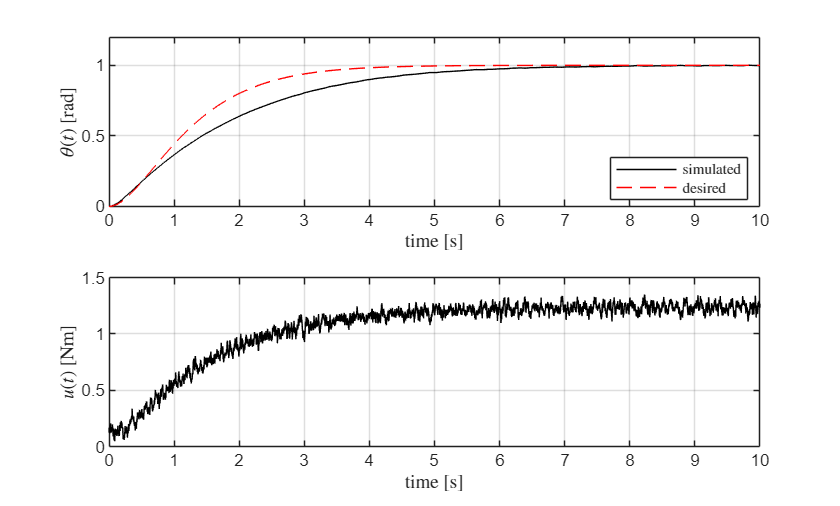

omega_o = 15*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

theta_nom = theta;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

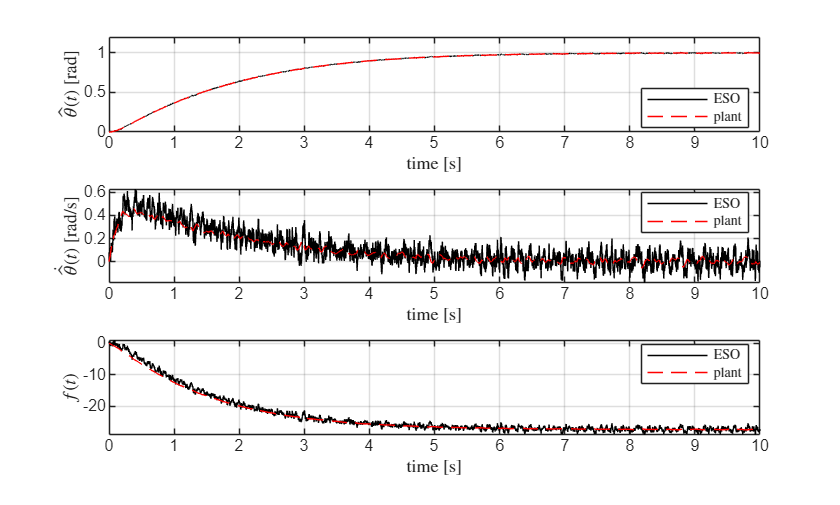

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\hat{\theta} (t)$ [rad]','Interpreter','latex');
grid on
ylim([0 1.2])

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
ylabel('$\dot{\hat{\theta}} (t)$ [rad/s]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'ESO', 'plant'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
xlabel('time [s]','Interpreter','latex');
ylabel('$f(t)$','Interpreter','latex');

Now let's change the pendulum parameters. 

Check the open loop response

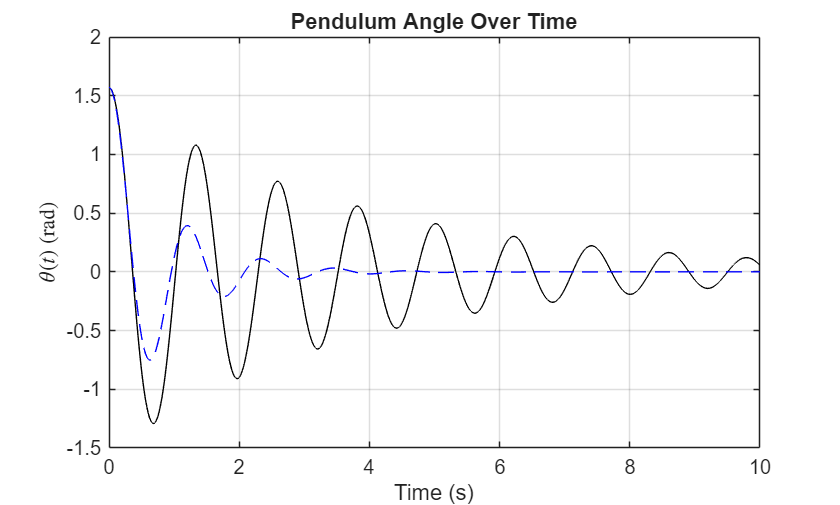

% Initialize pendulum variables
M = 0.8;    % [kg] mass of the pendulum tip
c = 0.05;
l = 0.35;

debug_mode = 0;      % debug mode flag (1=debug, 0=normal)
manual_control_flag = 1; % flag to switch from manual to adrc control (1=manual, 0=adrc)
u_manual = 0;   % [Nm] manual control action (motor torque)

theta_init = pi/2; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t_ol2 = simout.tout;
theta_ol2 = simout.yout{1}.Values.Data;

% Plot the results of the simulation
figure;
plot(t_ol2, theta_ol2, 'k');
hold on
plot(t_ol, theta_ol, '--b');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;

Now check the closed-loop response

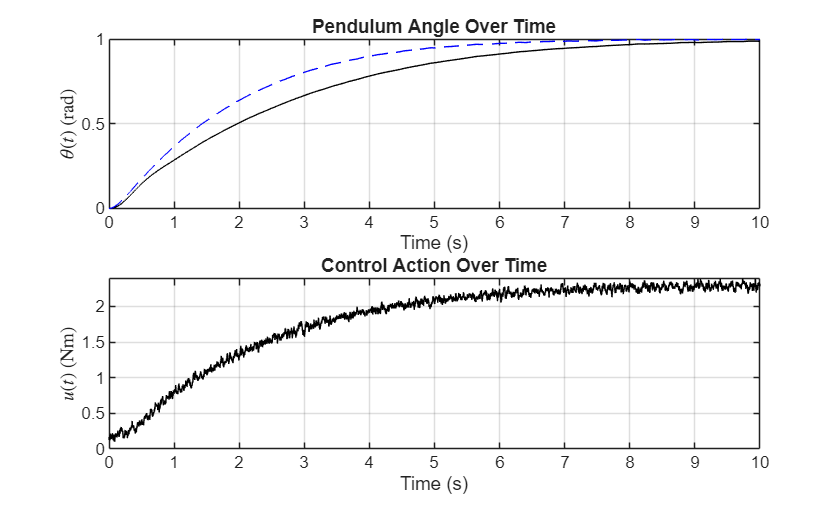

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;


% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
hold on
plot(t, theta_nom, '--b');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

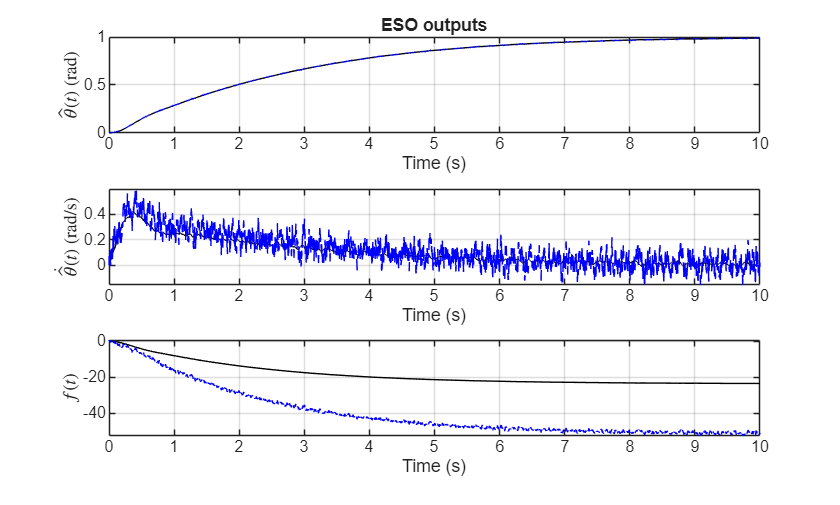


figure;
subplot(3,1,1)
plot(t, theta, 'k');
hold on 
plot(t, theta_hat, '--b');
xlabel('Time (s)');
ylabel('$\hat{\theta} (t)$ (rad)','Interpreter','latex');
grid on
title('ESO outputs');
subplot(3,1,2)
plot(t, theta_dot, 'k');
hold on 
plot(t, theta_hat_dot, '--b');
xlabel('Time (s)');
ylabel('$\dot{\hat{\theta}} (t)$ (rad/s)','Interpreter','latex');
grid on;
subplot(3,1,3)
plot(t, f, 'k');
hold on 
plot(t, f_hat, '--b');
grid on
xlabel('Time (s)');
ylabel('$f(t)$','Interpreter','latex');

Now correct the b0

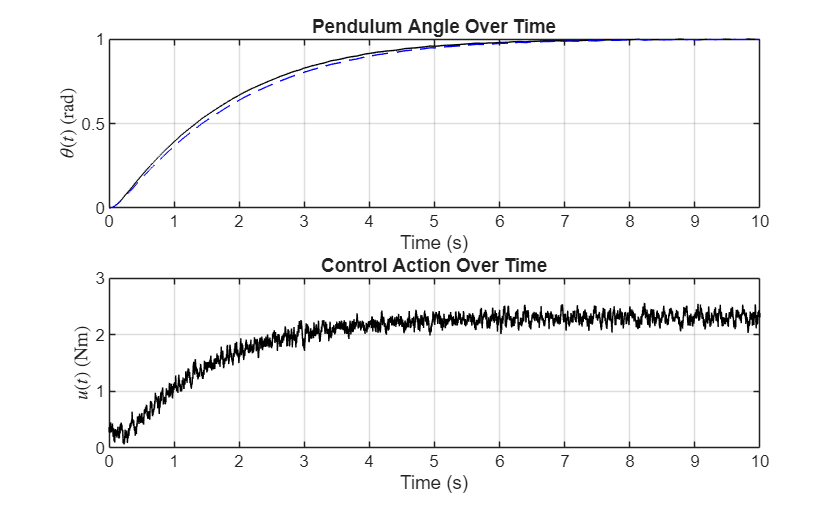

b0 = 1/(M*l^2);
B = [  0;
       b0;
       0  ];

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
hold on
plot(t, theta_nom, '--b');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

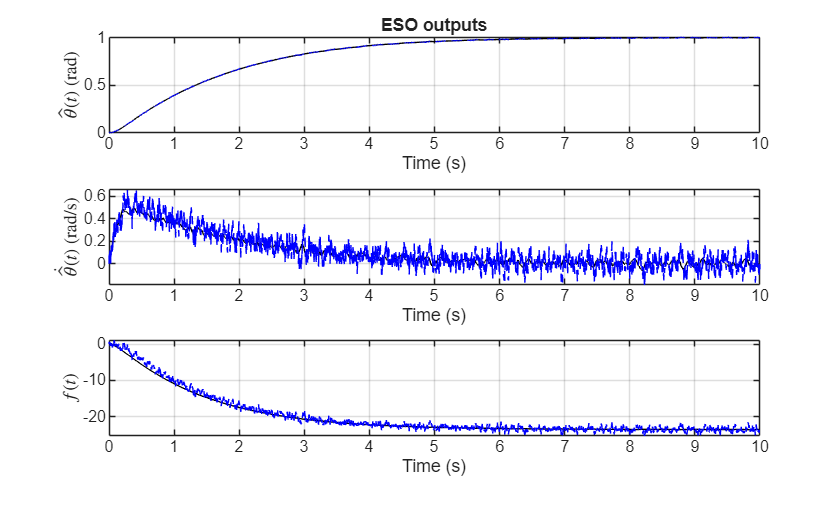


figure;
subplot(3,1,1)
plot(t, theta, 'k');
hold on 
plot(t, theta_hat, '--b');
xlabel('Time (s)');
ylabel('$\hat{\theta} (t)$ (rad)','Interpreter','latex');
grid on
title('ESO outputs');
subplot(3,1,2)
plot(t, theta_dot, 'k');
hold on 
plot(t, theta_hat_dot, '--b');
xlabel('Time (s)');
ylabel('$\dot{\hat{\theta}} (t)$ (rad/s)','Interpreter','latex');
grid on;
subplot(3,1,3)
plot(t, f, 'k');
hold on 
plot(t, f_hat, '--b');
grid on
xlabel('Time (s)');
ylabel('$f(t)$','Interpreter','latex');